# Introduction

The new version operates much like the R package rerddapXtracto.  There are two steps in getting data - the first is to get information about the dataset,  the second is to use that information in order to make an extract.  

## Main Functions

There are 6 main functions.  The first is used to find the information about the dataset:

- function [ info ] = erddapInfo( datasetID, varargin )

There are three extraction functions:

- function [extractStruct] = xtracto(dataInfo, parameter, xpos, ypos, varargin)

- function [extract] = xtracto_3D(dataInfo, parameter, xpos, ypos, varargin )

- function [extract, xlon, xlat, xtime] = xtractogon(dataInfo, parameter, xpoly, ypoly, varargin);

There are two mapping functions:

- function [] = makeMap_grid(extract, time_period, varargin)

- function [] = makeMap_track(extract, varargin)

### erddapInfo()

This function extracts necessary information about an ERDDAP dataset that is then use by the three data extraction functions. 'datasetD' is a string containing a valid ERDDAP datasetID,  say 'erdSWchla8day', and "varargin" is an optional second argument,  which if given is the base URL of the ERDDAP server.  The default URL if not given is 'https://coastwtch.pfeg.noaa.gov/erddap/"  (not the slash at the end).

### xtracto()

"xtracto()' is a function to extract data along a track in several dimensions. In "xtracto()",  xpos and ypos are vectors of the x-dimension and y-dimension positions along the track.  By default the x-dimension is named "longitude" and the y-dimension is named "latitude".  For datasets not on longitude-latitude grids,  such as projected data,  the names of these dimensions must be passed to the function by including terms such as ('xName', 'row', 'yName', 'col'). 

If the dataset has 'time' as a dimension,  then the times along the track can be added by including a cell-array of te values along the track in ISO format, say 'tpos' , by adding ('tpos', tpos) to the function call. 

If the dataset has another dimension,  say 'altitude' or 'depth', then an array of those values along the track, say 'zpos', must be added to the function  call as ('zpos', zpos). The default name for the this dimension is 'altitude'.  If that is not the name of the dimension,  then the actual name must be passed as ('zName', zName).

Finally,  due to error in positoning along a track,  or due to noise in the satellite data,  among other reasons, it can be desirable not to make an extra at the point but rather extract data in a box around the point in the track and then calcuate statistic on that extract.  This can be done by adding values for 'xlen', 'ylen' and 'zlen' where the box will have a width on half of the value.

So assuming 'datasetInfo' from calling 'erddapInfo()',  and 'parameter', 'xpos', 'ypos', 'tpos', 'xlen' and 'ylen' have all been defined, a call to 'xtracto()' would look like:

- extract = xtracto(datasetInfo, parameter, xpos, ypos, 'tpos', tpos, 'xlen', xlen, 'ylen', ylen);

The output of 'xtracto()' is a structure of the form:

- mean_parameter - mean of the parameter within the bounds of that time period

- std_parameter - standard deviation of the parameter within the bounds of that time period

- n - number of observations in the extract at each time period

- satellite_date - time of the actual request to the dataset at ech time period

- requested_xName_min - minimun x-axis value in request at each time period

- requested_xName_max - maximum x-axis value in request at each time period

- requested_yName_min - minimun y-axis value in request at each time period

- requested_yName_max - maximum y-axis value in request at each time period

- requested_zName_min - minimun z-axis value in request at each time period

- requested_zName_max - maximum z-axis value in request at each time period

- requested_date - date given in track

- median - median of the parameter within the bounds of that time period

- mad - Mean absolute deviation of the parameter within the bounds of that time period

where each field is the same length as the track.

#### Examples

Marlin tag data and chla

The file "Marlin38606.mat' contains tracks of a marlin courtesy of Dr. Mike Musyl of the Pelagic Research Group LLC.  First step is to load the dataset:

load('Marlin38606.mat');

To find seaWIFS 8-day chlorophyll along the track,  the datasetID for that dataset is 'erdSWchla8day' so the first step is get information about the dataset:

swchlInfo = erddapInfo('erdSWchla8day');

The next step is to setup this information in order to call 'xtracto.m':

xpos = Marlin38606.lon';
ypos = Marlin38606.lat';
tpos = Marlin38606.date;
tpos = datenum(tpos);
tpos = cellstr(datestr(tpos,'yyyy-mm-dd' ));
zpos = ones(numel(xpos))*0.;


Then the extract is made:

swchlExtract = xtracto_test(swchlInfo, 'chlorophyll', xpos, ypos, 'tpos', tpos, 'zpos', zpos, 'xlen', .2, 'ylen', .2);

The result can be mapped using "makeMap_track.m":

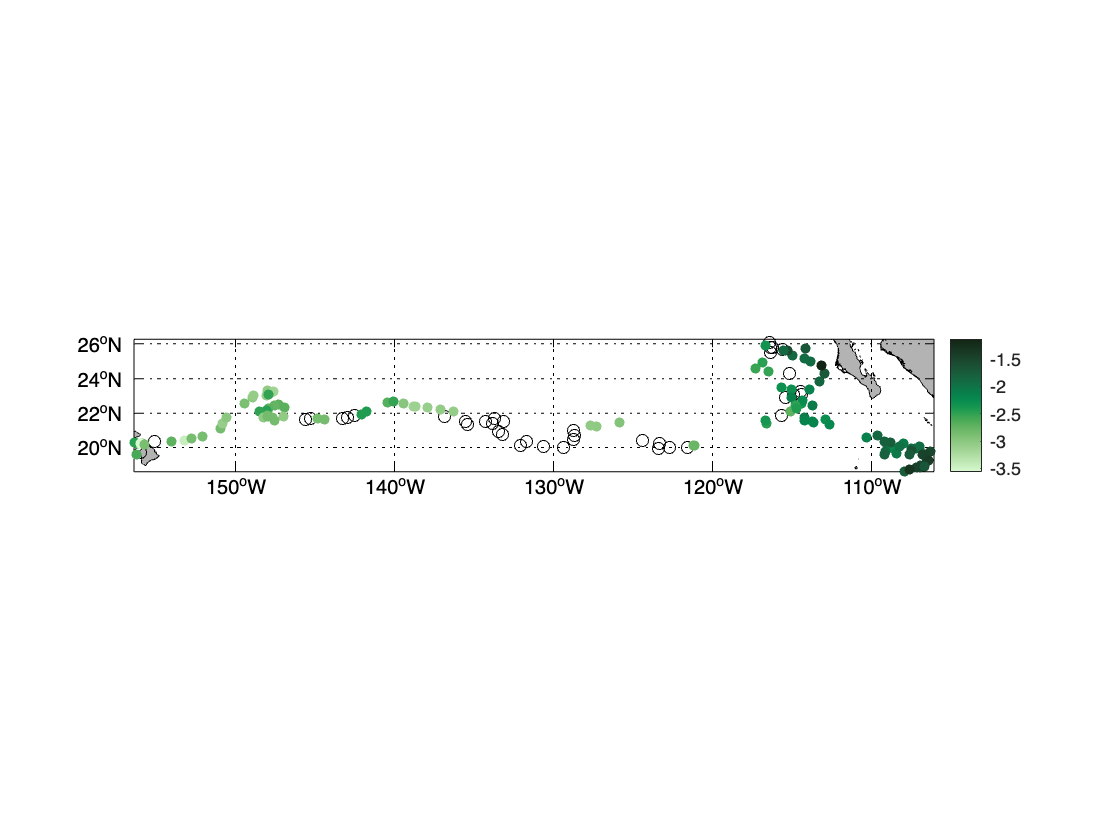

myfun = @(x)log(x);
makeMap_track(swchlExtract, 'c_map', 'algae', 'MyFunc', myfun)

Bathmetry along the track can also be extracted and plotted:

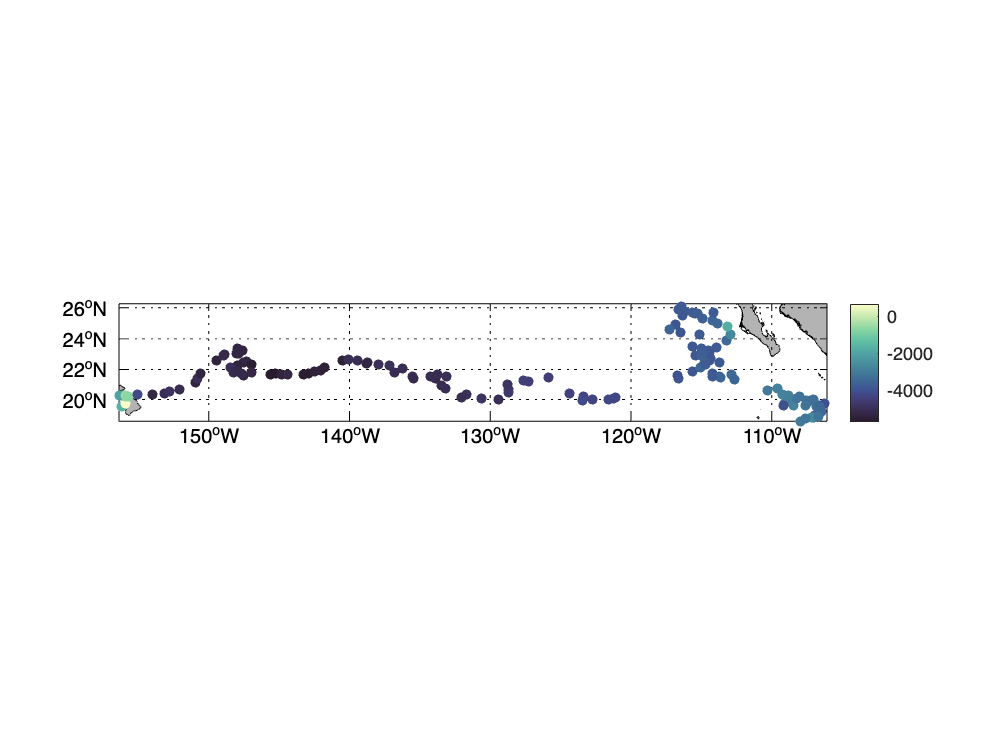

etopo_info = erddapInfo('etopo360');
etopo = xtracto_test(etopo_info, 'altitude', xpos, ypos, 'tpos', tpos, 'xlen', .2, 'ylen', .2 );
makeMap_track(etopo, 'c_map', '-deep');

### xtracto_3D()

'xtracto_3D()' is a function to extract from an ERDDAP server gridded data in a given bounding box.  'datasetInfo' is a result from calling 'erddapInfo()' for the give dataset, "xpos" and "ypos" are vectors of length 2 given the x-axis and y-axis extents of the bounding box.  By default it is assume that the names of the x- and y- axes are 'longitude'  and 'latitude'.  If not, say for projected data,  the actual names must be passed by addng to the call ('xName', xName, 'yName',  yName).

If the dataset has a third dimension, say 'altitude',  then the extents for that dimenson can be pass by a vector of length 2, say 'zpos',  by appending ('zpos', zpos) to the call.  The default for the 'z-axis' is 'altitude',  if this is not the name in the dataset,  the actual name can be appending to the function call ('zName', zname).

Finally if 'time' is a dimension,  than you must pass a cell-array of length 2 with the time extents in ISO format, say 'tpos' as ('tpos', tpos).

So for properly defined arrays 'xpos', 'ypos', 'zpos', 'tpos' and with 'datasetInfo' from a call to 'erddapInfo()',  a call to 'xtracto_3D()' would be:

- extract = xtracto_3D(datasetInfo', xpos, ypos, 'zpos', zpos, 'tpos', tpos);

'extract' is then a structure with all of the coordinate values as well as the extracted data. For exmple n the MODIS chlorophyll example below,  the returne structure is:

       time: [2×1 string

       altitude: 0

       latitude: [121×1 double]

      longitude: [201×1 double]

       chlorophyll: [2×1×121×201 double]

#### Examples

xpos = [235 240];
ypos = [36 39];
zpos = [0 0];
tpos{1} = '2018-01-16';
tpos{2} = '2018-03-16';
modis_info = erddapInfo('erdMBchlamday');
MODIS = xtracto_3D(modis_info, 'chlorophyll', xpos, ypos, 'tpos', tpos);


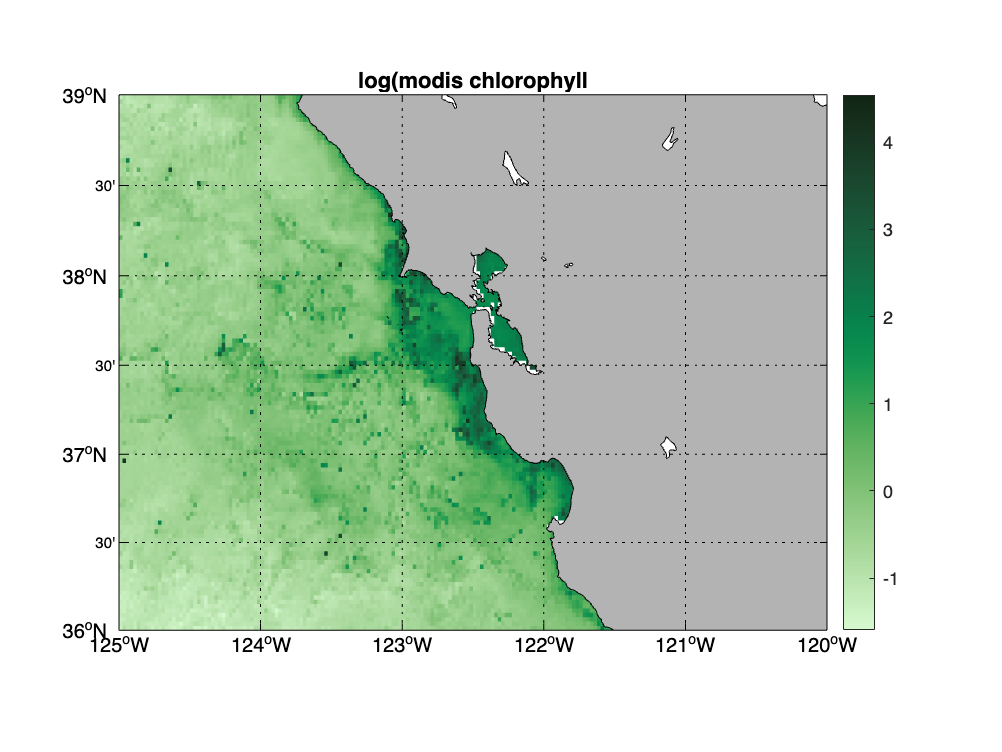

myfun = @(x)log(x);
makeMap_grid(MODIS, MODIS.time(1, :), 'myFunc', myfun, 'c_map', 'algae');
title('log(modis chlorophyll)');

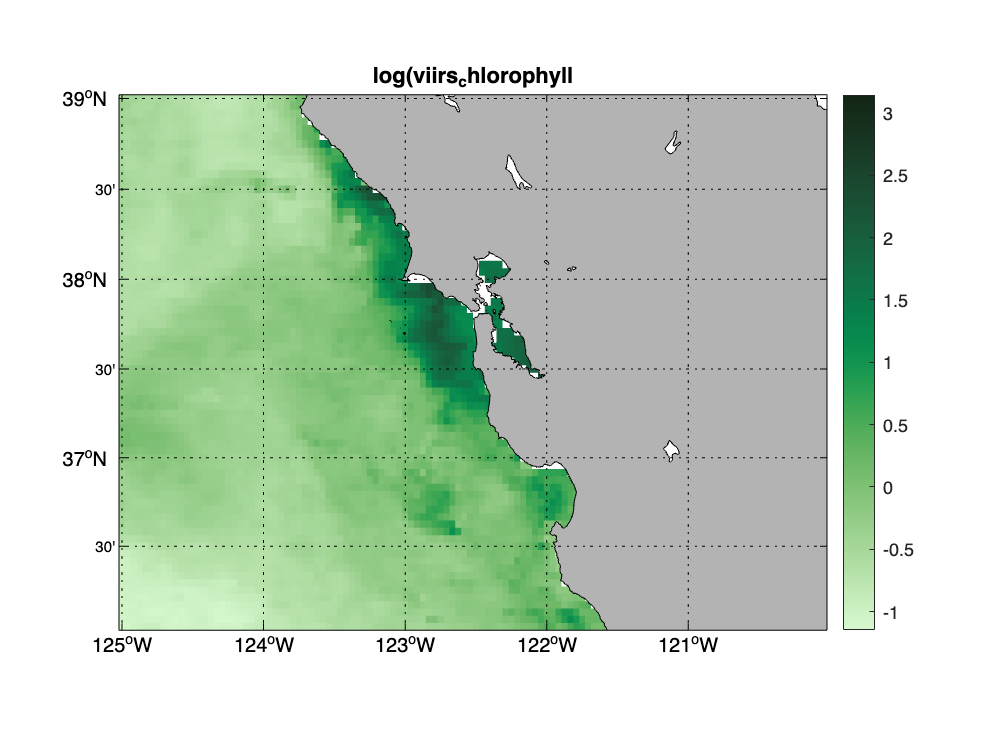

tpos{1} = '2012-01-15';
viirs_info = erddapInfo('erdVH3chlamday');
VIIRS = xtracto_3D(viirs_info, 'chla', xpos, ypos, 'tpos', tpos);
myfun = @(x)log(x);
makeMap_grid(VIIRS, VIIRS.time(1, :), 'myFunc', myfun, 'c_map', 'algae');
title('log(viirs_chlorophyll)');

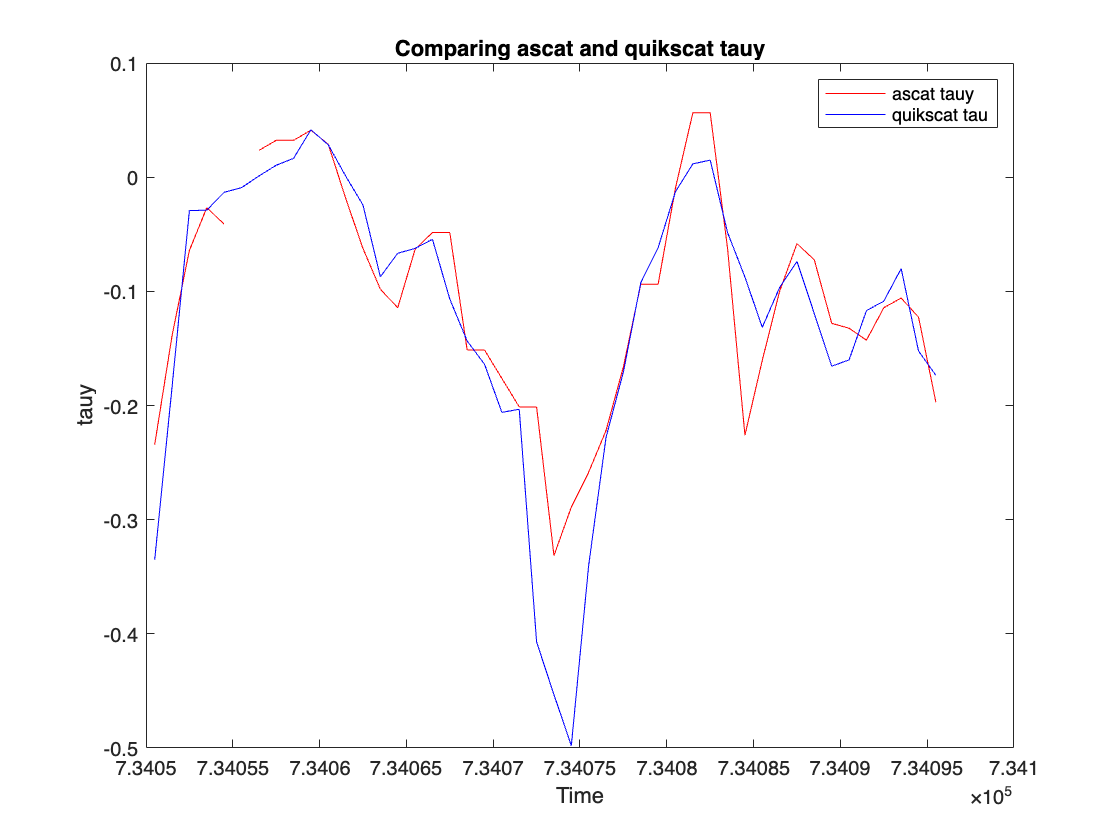

xpos = [237 237];
ypos = [36 36];
zpos = [0 0];
tpos{1} = '2009-10-05';
tpos{2} = '2009-11-19';
ascat_info = erddapInfo('erdQAstress3day');
ascat = xtracto_3D(ascat_info, 'tauy', xpos, ypos, 'tpos', tpos, 'zpos',  zpos);
quikscat_info = erddapInfo('erdQSstress3day');
quikscat = xtracto_3D(quikscat_info, 'tauy', xpos, ypos, 'tpos', tpos, 'zpos',  zpos);
times = erddap8601(ascat.time);
% Open a new figure window
figure;
% Plot the first dataset in red
plot(times, double(ascat.tauy), 'r', 'DisplayName', 'ascat tauy'); 
hold on; % Hold on to add the second plot
% Plot the second dataset in blue
plot(times, double(quikscat.tauy), 'b', 'DisplayName', 'quikscat tau'); 
% Adding labels and title
xlabel('Time');
ylabel('tauy');
title('Comparing ascat and quikscat tauy');
% Adding a legend
legend show;
% Release the hold
hold off;

### xtractogon.m

'xtractogon()' is a function that makes a dataset within a polygon defined by 'xpos' and 'ypos'.  The function is limited to datasets on an latitdute-longitude grid though there can be multiple time periods.  If there is a z-coordinate,  it cna only have one value.  Otherwise the arguments are the same as in 'xtracto_3D()'.

#### Examples

The file 'mbnms.mat' contains the boundaries of Monterey Bay National Marine Sanctuary, and we can use that to extract data only contained in the Sanctuary boundaries, for exampl chlorophyll (through time):

load('mbnms.mat');
tpos{1} = '2014-09-01';
tpos{2} = '2014-11-17';
xpoly = mbnms(:, 1);
ypoly = mbnms(:, 2);
sanctchl_info = erddapInfo('erdMH1chlamday');
sanctchl = xtractogon(sanctchl_info, 'chlorophyll', xpoly, ypoly, 'tpos', tpos);

And the result for one time-period can me graphed using 'makeMap_grid()':

myfun = @(x)log(x);

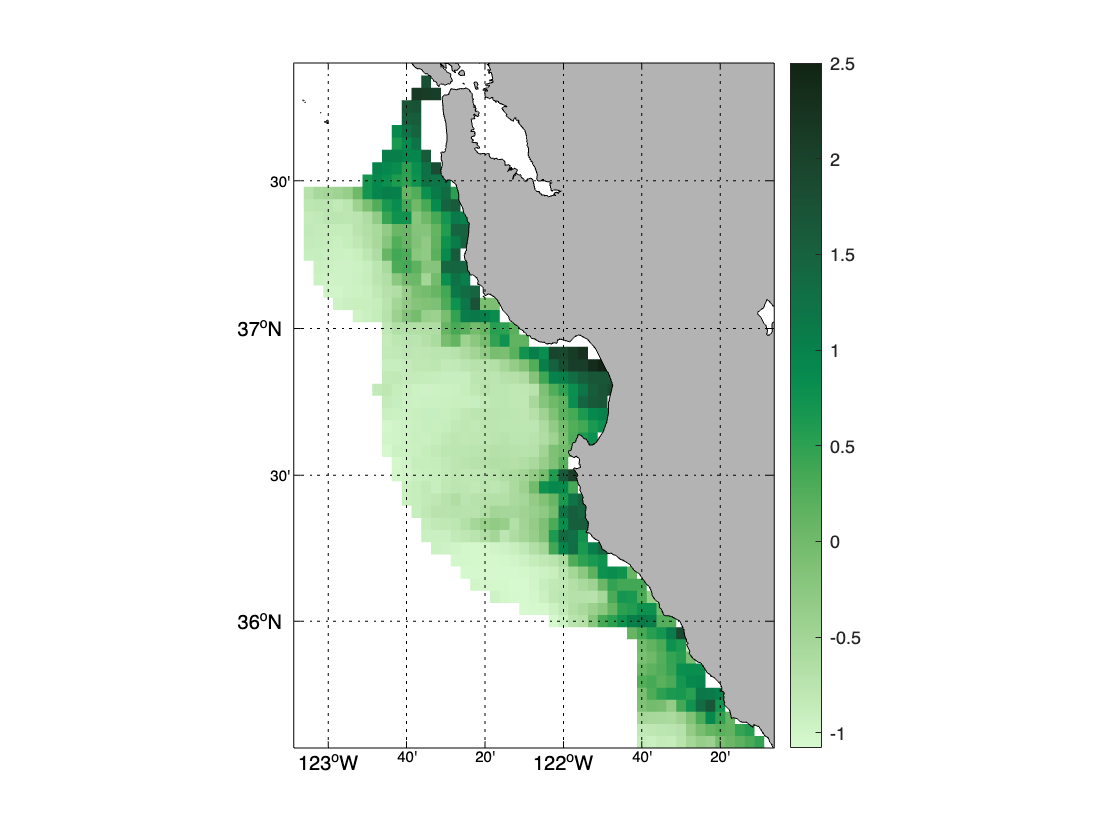

makeMap_grid(sanctchl, sanctchl.time(1, :), 'myFunc', myfun, 'c_map', 'algae');

Similarly the bathymetry can be accessed and mapped,  which show the famous canyons of Monterey Bay:

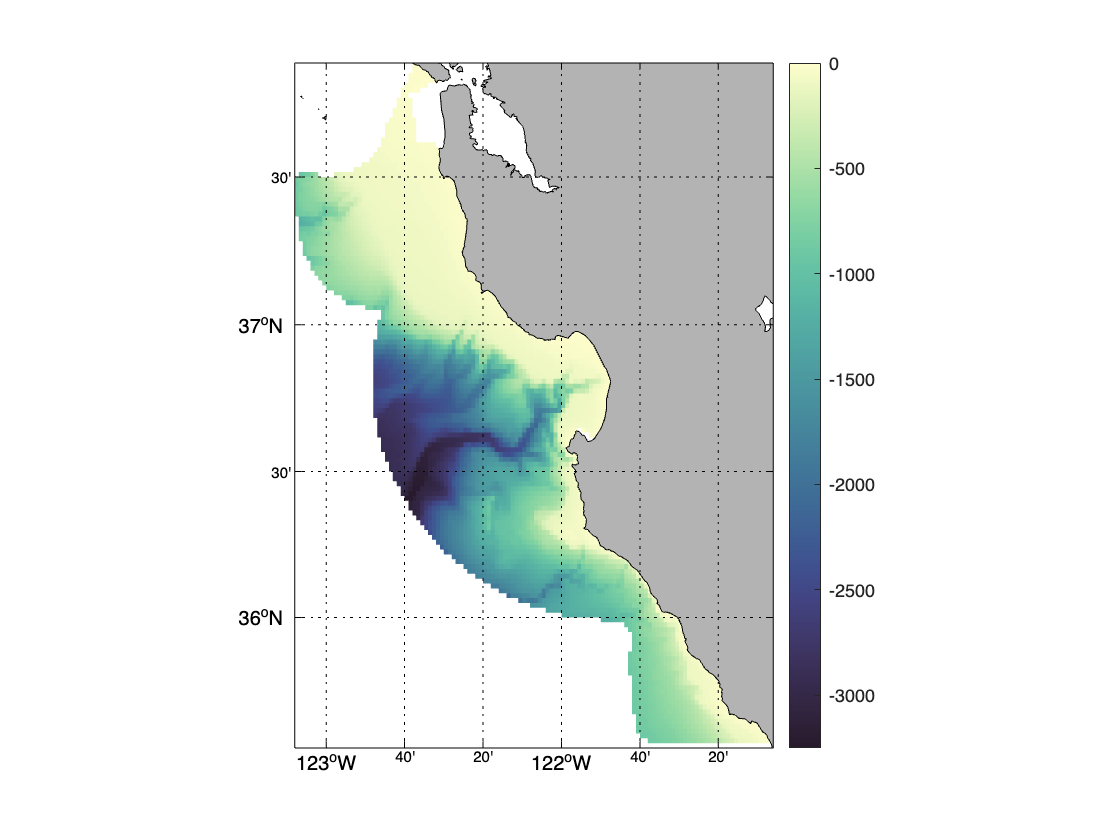

etopo_info = erddapInfo('etopo180');
etopo = xtractogon(etopo_info, 'altitude', xpoly, ypoly, 'tpos', tpos);
makeMap_grid(etopo, NaN,  'c_map', '-deep');

### makeMap_grid() and makeMap_track()

There are two mapping routines both of which require the 'm_map' package (https://www.eoas.ubc.ca/~rich/map.html) :

- function [] = makeMap_grid(extract, time_period, varargin)

- function [] = makeMap_track(extract,  varargin)

both of which have been used above.  'makeMap_grid()' is for output from 'xtracto_3D()' and 'xtractogon()' while 'makeMap_track()' is for output from 'xtracto()'.  The  allowable arguments in 'varagin' and their default values are:

- 'projection'  - 'mercator'

- 'c_map'   - 'parula'

- 'myFunc'  - @(x) x

where 'projection' can be any projection support by the 'm_map' package,; 'c_map' is the colormap which defaults to the Matlab  default 'parula' otherwise is one of the colorbars defined in the 'cmocean' package (https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps),  say 'algae' or 'deep' or 'balance'; and 'myFunc' is a lambda function used to transform the data before plotting.  In 'makeMap_grid()' , 'time_period' is the time period to be plotted, which must be one of the returned times,  say 'extract.time(1, :)' to plot the first time. If the dataset is only two-dimensional,  say a bathymetry extract,  pass 'NaN' for the time  (see example below).

All of the examples above demonstrate the use of these functions.